clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;
A_JOHNogKarsten = cell(1,param.n)

A_JOHNogKarsten = 1×4 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


for i = 1:param.n
    A_JOHNogKarsten{i} = [-(param.ctrl.q_OP(i)/param.thermo.V_w(i) + param.thermo.B(i)/(param.thermo.C_w*param.thermo.rho_w*param.thermo.V_w(i))) param.thermo.B(i)/(param.thermo.C_w*param.thermo.rho_w*param.thermo.V_w(i)), 0;
                                param.thermo.B(i)/(param.thermo.C_a*param.thermo.rho_a*param.thermo.V_a(i)), -(param.ctrl.Q(i)/param.thermo.V_a(i) +param.thermo.B(i)/(param.thermo.C_a*param.thermo.rho_a*param.thermo.V_a(i))),0;
                                0, 1, 0];
end
param.model.A = blkdiag(A_JOHNogKarsten{:})

param = struct with fields:
    thermo: [1×1 struct]
      ctrl: [1×1 struct]
      pipe: [1×1 struct]
      pump: [1×1 struct]
     model: [1×1 struct]
         n: 4


eig(blkdiag(A_JOHNogKarsten{:}))

ans =          0
         0
         0
         0
   -4.0442
   -0.0312
   -0.0311
   -4.0059
   -0.0311
   -4.0059


%eig(param.model.A)



%param.model.A = -10*eye(12);
%param.model.B_Bar = blkdiag(ones(3,1),ones(3,1),ones(3,1),ones(3,1));
%param.model.B = blkdiag(ones(3,1),ones(3,1),ones(3,1),ones(3,1));
%param.model.B = ones(12,4);
%param.model.B_Bar = ones(12,4);

## Control

[param.ctrl.Ks res] = control.DesignProcedure1(param,0); 

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0508
       solvertime: 0.0129
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


LPV
eig LPV


ans = 1.0e+03 *

   -0.0010
   -0.0010
   -0.0010
   -0.0010
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


Evaluation of design procedure 1 
cali_Q is positive definite


ans =     0.3021    0.3034    0.3034    0.3034    0.7871    0.7871    0.7871    0.7884    2.0153    2.0153    2.0153    2.0161


cali_R is positive definite


ans = 1.0e-10 *

    0.0005    0.0005    0.0005    0.0005    0.0022    0.0024    0.0025    0.0026    0.1016    0.1219    0.1391    0.1421


Tau is found to be:


ans = 2.8753e-18

Eigenvalues of the decoupled systems are all negative 


ans =   -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2415 + 4.0904i  -1.2415 - 4.0904i  -0.2806 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -0.2654 + 6.8268i  -0.2654 - 6.8268i  -0.4921 + 6.3060i  -0.4921 - 6.3060i  -1.0512 + 4.7360i  -1.0512 - 4.7360i  -0.8367 + 5.4247i  -0.8367 - 5.4247i  -0.2776 + 0.0000i  -0.2752 + 0.0000i  -0.2724 + 0.0000i  -0.2733 + 0.0000i


eigenvalues of A


ans =          0
         0
         0
         0
   -4.0442
   -0.0312
   -0.0311
   -4.0059
   -0.0311
   -4.0059


eigenvlaues of Bk


ans =     3.2342
    2.7815
    1.6631
    2.1183
         0
         0
         0
         0
         0
         0


res = 0

%param.ctrl.Ks = control.DesignProcedure2(param,0);

%param.ctrl.Ks = control.DesignProcedureDScalingDiag(param,0);
%param.ctrl.Ks = control.DesignProcedureFunky(param,0);
%param.ctrl.Ks = control.DesignRobust(param,0

## Scaled design

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


% C = blkdiag([0 0 0; 0 1 0; 0 0 0],[0 0 0; 0 1 0; 0 0 0],[0 0 0; 0 1 0; 0 0 0],[0 0 0; 0 1 0; 0 0 0])
C = blkdiag([0 1 0],[0 1 0],[0 1 0],[0 1 0])

C =      0     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0


G = C/(s*eye(12)-param.model.A)*param.model.B_Bar

G =
 
  From input 1 to output...
              -0.3874
   1:  ----------------------
       s^2 + 4.037 s + 0.1247
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
              -0.6714
   2:  ----------------------
       s^2 + 4.075 s + 0.1261
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
              -0.7749
   3:  ----------------------
       s^2 + 4.037 s + 0.1247
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
              -0.4641
   4:  ----------------------
       s^2 + 4.037 s + 0.1245
 
Continuous-time transfer function.


% 
% wp = eye(12);
% wd = eye(4);
% 
% P = [zeros(4) zeros(4,12) wd;
%      wp*G  wp wp*G;
%      -G -eye(12) -G];
% %%%%% P11 1:16 x 1:16 
% %%%%% P12 1:16 x 17:20
% %%%%% P21 17:28 x 1:16
% %%%%% P22 17:28 x 17:20
K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4))

K =    -9.8753   60.8510   12.9842         0         0         0         0         0         0         0         0         0
         0         0         0   -5.8986   35.9303    7.6361         0         0         0         0         0         0
         0         0         0         0         0         0   -4.9376   30.4255    6.4921         0         0         0
         0         0         0         0         0         0         0         0         0   -8.2431   50.7971   10.8390


L = -K/(s*eye(12)-param.model.A)*param.model.B_Bar

L =
 
  From input 1 to output...
            -1.28 s^2 + 18.47 s + 5.031
   1:  --------------------------------------
       s^3 + 4.037 s^2 + 0.1247 s + 1.749e-19
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
            -1.312 s^2 + 18.84 s + 5.127
   2:  --------------------------------------
       s^3 + 4.075 s^2 + 0.1261 s + 3.569e-19
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
            -1.28 s^2 + 18.47 s + 5.031
   3:  --------------------------------------
       s^3 + 4.037 s^2 + 0.1247 s - 1.349e-19
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
            -1.279 s^2 + 18.47 s + 5.031
   4:  --------------------------------------
       s^3 + 4.037 s^2 + 0.1245 s + 5.569e-20
 
Continuous-time transfer function.




%Ks = K/(-s*eye(12)-param.model.A-param.model.B_Bar*K)
%Ks = (ss(param.model.A-param.model.B_Bar*K,[0 1 0 0 1 0 0 1 0 0 1 0]',C,0));
% 
% N =  P(1:16,1:16) + P(1:16,17:20)*K/(eye(12)-P(17:end,17:end)*K)*P(17:end,1:16);
% 
% N11 = -K*G/(eye(4)+K*G);
% N22 = wp/(eye(12)+G*K); 
% find(eig(N11)>0)
% hinfnorm(N11)
% 
% eig(param.model.A+param.model.B_Bar*K)
% 
% SSSYS = ss(param.model.A,param.model.B_Bar,eye(12),zeros(12,4));
% CL = feedback(SSSYS,K);
% 
% eig(CL)
% eig(SSSYS.A+SSSYS.B*K)
% 
% % 
% % 
% % L = sdpvar(4);
% % constraints = [L>=0]
% % options = sdpsettings('verbose',0,'solver','mosek');
% % 
% %  sol = optimize(constraints,hinfnorm(L*N2/L),options)
% 
% m =4
% ii = rand(m);
% L = ii*ii.';
% L = diag([L(1,1),L(2,2),L(3,3),L(4,4)])
% eig(L)
% % L = [0.1 0 0 0;
% %      0 0.1 0 0;
% %      0 0 0.2 0;
% %      0 0 0 0.3];
% N2normScaled = hinfnorm(L*N11/L)
% N2norm = hinfnorm(N11)
% 
% eig(N11) 





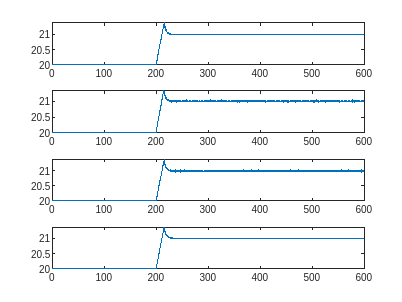

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);
coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,1)-273.15)
end